file_num = 2;

path = root_dir + "/" + testdate + "/qualsis_data/*Ollie*.mat";
file_names = dir(path)

file_names = 4×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


current_file = file_names(file_num);
data = load(strcat(current_file.folder, '\', current_file.name));
fnames = fieldnames(data);
data = data.(fnames{1});

trajectories = data.Trajectories.Unidentified.Data;
qualsis_time = (1:1:data.Frames)/data.FrameRate;

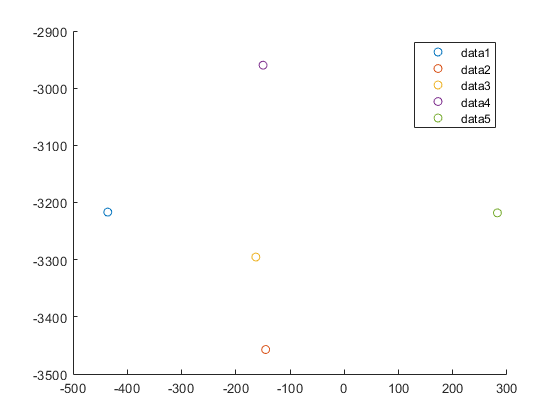

clf
hold on
scatter3(trajectories(1,1,1), trajectories(1,2,1), trajectories(1,3,1))
scatter3(trajectories(2,1,1), trajectories(2,2,1), trajectories(2,3,1))
scatter3(trajectories(3,1,1), trajectories(3,2,1), trajectories(3,3,1))
scatter3(trajectories(4,1,1), trajectories(4,2,1), trajectories(4,3,1))
scatter3(trajectories(5,1,1), trajectories(5,2,1), trajectories(5,3,1))
legend
hold off

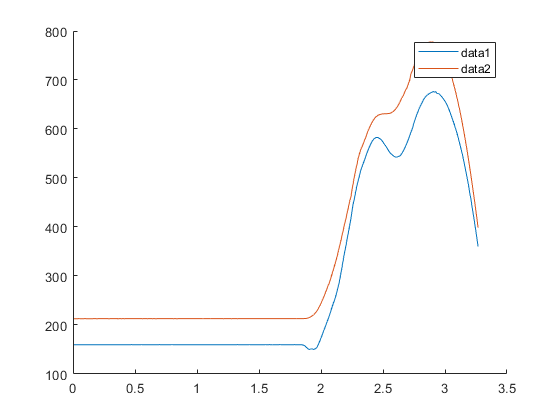

axis = 3;
clf
hold on
plot(qualsis_time, squeeze(trajectories(2,axis,:)))
plot(qualsis_time, squeeze(trajectories(3,axis,:)))
hold off
legend

point1 = squeeze(trajectories(3,1:3,:));
point1 = point1(1:3, :);
point2 = squeeze(trajectories(2,1:3,:));
point2 = point2(1:3, :);

diff12_Z = point1(3, :) - point2(3,:);
diff12_Y = point1(2, :) - point2(2,:);
diff12_X = point1(1, :) - point2(1,:);

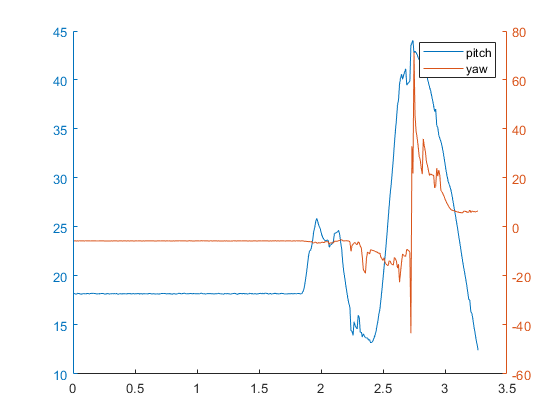

clf
hold on

yyaxis left
plot(qualsis_time,atand(diff12_Z./diff12_Y), 'DisplayName', "pitch")

yyaxis right
plot(qualsis_time,atan2d(diff12_Y./diff12_X, 90), 'DisplayName', "yaw")
hold off
legend

point3 = squeeze(trajectories(1,1:3,:));
point3 = point3(1:3, :);
point4 = squeeze(trajectories(5,1:3,:));
point4 = point4(1:3, :);

diff34_Z = point3(3, :) - point4(3,:);
diff34_Y = point3(2, :) - point4(2,:);
diff34_X = point3(1, :) - point4(1,:);

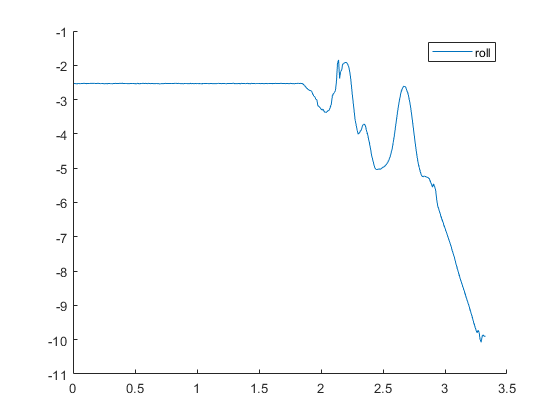

clf
hold on
plot(qualsis_time,atand(diff34_Z./diff34_X), 'DisplayName', "roll")
hold off
legend

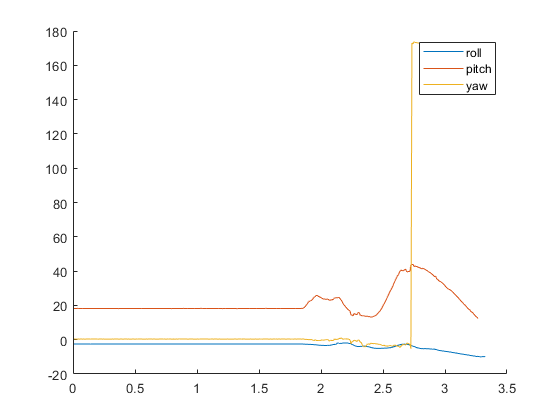

roll = atand(diff34_Z./diff34_X);
pitch = atand(diff12_Z./diff12_Y);
yaw = atand(diff12_Y./diff12_X);
clf
hold on
plot(qualsis_time,roll, 'DisplayName', "roll")
plot(qualsis_time,pitch, 'DisplayName', "pitch")
plot(qualsis_time,yaw+84, 'DisplayName', "yaw")
hold off
legend

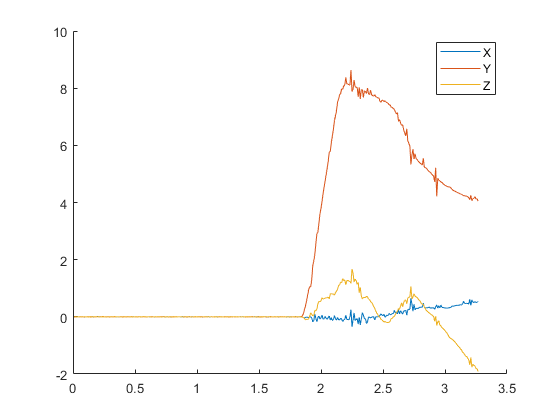

centrePositions = 0.5*(point1+point2);

velocities = [0, diff(centrePositions(1,:))./diff(qualsis_time);...
              0, diff(centrePositions(2,:))./diff(qualsis_time);...
              0, diff(centrePositions(3,:))./diff(qualsis_time)]*1e-3;

clf
hold on
plot(qualsis_time,velocities(1,:), 'DisplayName', "X")
plot(qualsis_time,velocities(2,:), 'DisplayName', "Y")
plot(qualsis_time,velocities(3,:), 'DisplayName', "Z")
hold off
legend

qualsis_v = vecnorm(velocities);

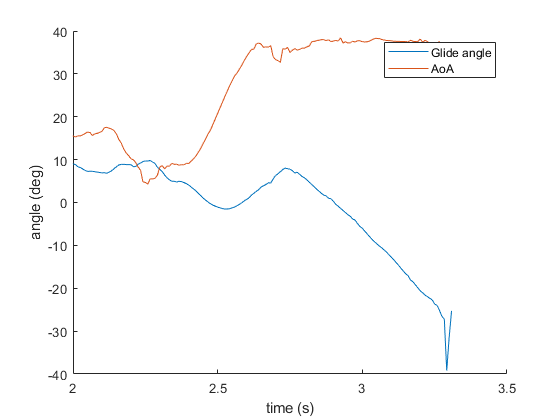

glideAngle = smooth(qualsis_time,atand(velocities(3,:)./velocities(2,:)),12,'sgolay')';
angleOfAttack = pitch - glideAngle;

clf
hold on
plot(qualsis_time,glideAngle, 'DisplayName', "Glide angle")
plot(qualsis_time,angleOfAttack, 'DisplayName', "AoA")
hold off
legend
xlabel("time (s)")
ylabel("angle (deg)")
xlim([2,3.5])